% Link Lengths
L1x = 0.62; 
L1y = 0.19; 
L2 = 0.325; 
L3 = 0.16; 
L4 = 0.18; 
L5x = 0.1; 
L5y = 0.16; 
L6 = 0.35;

lg2 = 0.17115; 
lg3 = 0.09026; 
lg4 = 0.09; 
lg6 = 0.175;

rho = 30000;
T = 0.02;
R_Hole = 0.0125;
R_Link = 0.02;

% MOI
I2 = 0.089191665; 
I3 = 0.01389689; 
I4 = 0.01435385; 
I6 = 0.130437;

% Angular Position, Velocity, and Acceleration (Link 2)
theta2 = 54.12*pi/180; 
omega2 = -25; 
alpha2 = -15;

% Input parameters
tau = 10;
Fp = 279;
lf = 0.0279;

% 1.
syms theta3 theta4 theta5 theta6 real

D_Pos = Position(L2, theta2);
E_Pos = Position((L2-0.08), theta2);
B_Pos = D_Pos + Position(L3, theta3);
A_Pos = B_Pos + Position(L4, theta4);
C_Pos = E_Pos + Position(L6, theta6);
End = Position(sqrt(L1x^2 + L1y^2), atan(L1y/L1x));

% Equation to solve theta5 and theta6
eq1 = C_Pos - Position(L5x, theta5) - Position((L5y - 0.08), (theta5 - pi/2)) == End;

sol1 = solve(eq1, [theta5, theta6]);

theta5_val = mod(rad2deg(double(sol1.theta5(2))), 360);
theta6_val = mod(rad2deg(double(sol1.theta6(2))), 360);

theta5 = sol1.theta5(2);
theta6 = sol1.theta6(2);

eq2 = A_Pos - Position(L5x, theta5) - Position(L5y, (theta5 - pi/2)) == End;
    
sol2 = solve(eq2, [theta3, theta4]);

theta3_val = mod(rad2deg(double(real(sol2.theta3(1)))), 360);
theta4_val = mod(rad2deg(double(real(sol2.theta4(1)))), 360);

% Display the solutions in degrees within [0, 360]

fprintf('theta3 = %.2f degrees\n', theta3_val);

theta3 = 39.13 degrees


fprintf('theta4 = %.2f degrees\n', theta4_val);

theta4 = 312.37 degrees


fprintf('theta5 = %.2f degrees\n', theta5_val);

theta5 = 225.34 degrees


fprintf('theta6 = %.2f degrees\n', theta6_val);

theta6 = 356.16 degrees


D_Pos = Position(L2, theta2)

D_Pos = 0.1905 + 0.2633i

E_Pos = Position((L2-0.08), theta2)

E_Pos = 0.1436 + 0.1985i

B_Pos = D_Pos + Position(L3, deg2rad(theta3_val))

B_Pos = 0.3146 + 0.3643i

A_Pos = B_Pos + Position(L4, deg2rad(theta4_val))

A_Pos = 0.4359 + 0.2313i

C_Pos = E_Pos + Position(L6, deg2rad(theta6_val))

C_Pos = 0.4928 + 0.1751i

End

End = 0.6200 + 0.1900i

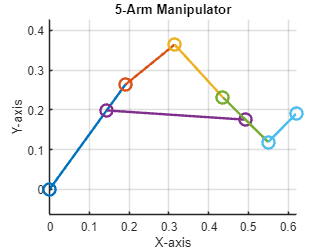

% Plot the manipulator
figure;

L_Pos = End + Position(L5x, deg2rad(theta5_val));

hold on;
plot([0, real(D_Pos)], [0, imag(D_Pos)], 'o-','LineWidth', 2, 'MarkerSize', 10);
plot([real(D_Pos), real(B_Pos)], [imag(D_Pos), imag(B_Pos)], 'o-','LineWidth', 2, 'MarkerSize', 10);
plot([real(A_Pos), real(B_Pos)], [imag(A_Pos), imag(B_Pos)], 'o-','LineWidth', 2, 'MarkerSize', 10);
plot([real(E_Pos), real(C_Pos)], [imag(E_Pos), imag(C_Pos)], 'o-','LineWidth', 2, 'MarkerSize', 10);
plot([real(A_Pos), real(L_Pos)], [imag(A_Pos), imag(L_Pos)], 'o-','LineWidth', 2, 'MarkerSize', 10);
plot([real(L_Pos), real(End)], [imag(L_Pos), imag(End)], 'o-','LineWidth', 2, 'MarkerSize', 10);

% Adjust axis and display
axis equal;
title('5-Arm Manipulator');
xlabel('X-axis');
ylabel('Y-axis');
grid on;
hold off;

syms theta2 theta3 theta4 theta5 theta6 real

% Define symbolic variables for angular velocities
syms omega3 omega4 omega5 omega6 real

% Define the position functions
D_Pos = Position(L2, theta2);
E_Pos = Position((L2-0.08), theta2);
B_Pos = D_Pos + Position(L3, theta3);
A_Pos = B_Pos + Position(L4, theta4);
C_Pos = E_Pos + Position(L6, theta6);
End = Position(sqrt(L1x^2 + L1y^2), atan(L1y/L1x));

eq3 = C_Pos - Position(L5x, theta5) - Position((L5y - 0.08), (theta5 - pi/2)) == End;
eq4 = A_Pos - Position(L5x, theta5) - Position(L5y, (theta5 - pi/2)) == End;

eq3 = [diff(eq3, theta2) diff(eq3, theta5) diff(eq3, theta6)] * [omega2; omega5; omega6];
eq4 = [diff(eq4, theta2) diff(eq4, theta3) diff(eq4, theta4) diff(eq4, theta5)] * [omega2; omega3; omega4; omega5];

theta = [theta2, theta3, theta4, theta5, theta6];
theta_values = [54.12*pi/180, deg2rad(theta3_val), deg2rad(theta4_val), deg2rad(theta5_val), deg2rad(theta6_val)];

eq3 = subs(eq3, theta, theta_values);
eq4 = subs(eq4, theta, theta_values);

sol3 = solve(eq3, [omega5, omega6]);

omega5_value = double(real(sol3.omega5))

omega5_value = 222.0565

omega6_value = double(real(sol3.omega6))

omega6_value = -70.5983


eq4 = subs(eq4, omega5, omega5_value);

sol4 = solve(eq4, [omega3, omega4]);

omega3_value = double(real(sol4.omega3))

omega3_value = -100.5533

omega4_value = double(real(sol4.omega4))

omega4_value = -194.8605

syms theta2 theta3 theta4 theta5 theta6 real

% Define symbolic variables for angular velocities
syms omega2 omega3 omega4 omega5 omega6 real

syms alpha2 alpha3 alpha4 alpha5 alpha6 real

eq5 = C_Pos - Position(L5x, theta5) - Position((L5y - 0.08), (theta5 - pi/2)) == End;
eq6 = A_Pos - Position(L5x, theta5) - Position(L5y, (theta5 - pi/2)) == End;

eq5 = [diff(eq5, theta2) diff(eq5, theta5) diff(eq5, theta6)] * [omega2; omega5; omega6];
eq6 = [diff(eq6, theta2) diff(eq6, theta3) diff(eq6, theta4) diff(eq6, theta5)] * [omega2; omega3; omega4; omega5];

eq5 = [diff(eq5, theta2) diff(eq5, theta5) diff(eq5, theta6) diff(eq5, omega5) diff(eq5, omega6)] * [omega2; omega5; omega6; alpha5; alpha6];
eq6 = [diff(eq6, theta2) diff(eq6, theta3) diff(eq6, theta4) diff(eq6, theta5) diff(eq6, omega2) diff(eq6, omega3) diff(eq6, omega4) diff(eq6, omega5)] * [omega2; omega3; omega4; omega5; alpha2; alpha3; alpha4; alpha5];

omega = [omega2, omega3, omega4, omega5, omega6];
omega_values = [-25, omega3_value, omega4_value, omega5_value, omega6_value];

eq5 = subs(eq5, theta, theta_values);
eq6 = subs(eq6, theta, theta_values);

eq5 = subs(eq5, omega, omega_values);
eq6 = subs(eq6, omega, omega_values);

sol5 = solve(eq5, [alpha5, alpha6]);

alpha5_value = double(real(sol5.alpha5))

alpha5_value = -3.4363e+05

alpha6_value = double(real(sol5.alpha6))

alpha6_value = 1.2728e+05


eq6 = subs(eq6, alpha2, -15);
eq6 = subs(eq6, alpha5, alpha5_value);

sol6 = solve(eq6, [alpha3, alpha4]);

alpha3_value = double(real(sol6.alpha3))

alpha3_value = 1.4187e+05

alpha4_value = double(real(sol6.alpha4))

alpha4_value = 3.2771e+05


alpha = [alpha2, alpha3, alpha4, alpha5, alpha6];
alpha_values = [-15, alpha3_value, alpha4_value, alpha5_value, alpha6_value];

% 2.
M1 = ((R_Link * 2) * (L5x + R_Link))

M1 = 0.0048

M1_1 = (pi * R_Link * R_Link) / 2

M1_1 = 6.2832e-04

M2 = (pi * R_Hole * R_Hole)

M2 = 4.9087e-04

M3 = ((R_Link * 2) * (L5y - R_Link))

M3 = 0.0056

M3_1 = (pi * R_Link * R_Link) / 2

M3_1 = 6.2832e-04

M4 = (pi * R_Hole * R_Hole)

M4 = 4.9087e-04

M5 = (pi * R_Hole * R_Hole)

M5 = 4.9087e-04


C1 = [(R_Link + L5x) / 2, R_Link]

C1 =     0.0600    0.0200


C1_1 = [R_Link + L5x + ((4 * R_Link) / (3 * pi)), R_Link]

C1_1 =     0.1285    0.0200


C2 = [L5x + R_Link, R_Link]

C2 =     0.1200    0.0200


C3 = [R_Link, (R_Link * 2) + ((L5y - R_Link) / 2)]

C3 =     0.0200    0.1100


C3_1 = [R_Link, (L5y + R_Link) + ((4 * R_Link) / (3 * pi))]

C3_1 =     0.0200    0.1885


C4 = [R_Link, L5y + R_Link - 0.08]

C4 =     0.0200    0.1000


C5 = [R_Link, L5y + R_Link]

C5 =     0.0200    0.1800



lg5x = (M1*C1(1) + M1_1*C1_1(1) + M2*C2(1) + M3*C3(1) + M3_1*C3_1(1) + M4*C4(1) + M5*C5(1)) / (M1 + M1_1 + M2 + M3 + M3_1 + M4 + M5);
lg5y = (M1*C1(2) + M1_1*C1_1(2) + M2*C2(2) + M3*C3(2) + M3_1*C3_1(2) + M4*C4(2) + M5*C5(2)) / (M1 + M1_1 + M2 + M3 + M3_1 + M4 + M5);
lg5 = [L5x - R_Link - lg5x, lg5y]

lg5 =     0.0364    0.0754


% 3.
I_Hole1 = (M4 * (R_Hole^2) / 2) + Parallel_Axis(M4, C4)

I_Hole1 = 6.0880e-07

I_Hole2 = (M5 * (R_Hole^2) / 2) + Parallel_Axis(M5, C5)

I_Hole2 = 5.6825e-06

I_x = (M1 * ((R_Link * 2)^2 + (L5x + R_Link)^2) / 12) + Parallel_Axis(M1, C1)

I_x = 2.2423e-05

I_y = (M3 * ((R_Link * 2)^2 + (L5y - R_Link)^2) / 12) + Parallel_Axis(M3, C3)

I_y = 1.9716e-05

I_Halfx = (1/2 - 16/(9*pi*pi)) * M1_1 * (R_Link^2) + Parallel_Axis(M1_1, C1_1)

I_Halfx = 6.5365e-06

I_Halfy = (1/2 - 16/(9*pi*pi)) * M3_1 * (R_Link^2) + Parallel_Axis(M3_1, C3_1)

I_Halfy = 8.4659e-06

I_z = M2 * (R_Hole * 2^2) / 2 + Parallel_Axis(M2, C2)

I_z = 1.6644e-05


I5 = I_x + I_y + I_z + I_Halfy + I_Halfx - I_Hole2 - I_Hole1

I5 = 6.7494e-05

I5 = I5 * T * rho

I5 = 0.0405

% 4.
syms theta2 theta3 theta4 theta5 theta6 real

syms omega3 omega4 omega5 omega6 real

syms alpha3 alpha4 alpha5 alpha6 real

L2C = Position(lg2, theta2);
Ag2 = [diff(L2C, theta2) diff(L2C, theta3) diff(L2C, theta4) diff(L2C, theta5) diff(L2C, theta6)] * [omega2; omega3; omega4; omega5; omega6];
Ag2 = [diff(L2C, theta2) diff(L2C, theta3) diff(L2C, theta4) diff(L2C, theta5) diff(L2C, theta6) diff(L2C, omega2) diff(L2C, omega3) diff(L2C, omega4) diff(L2C, omega5) diff(L2C, omega6)] * [omega2; omega3; omega4; omega5; omega6; alpha2; alpha3; alpha4; alpha5; alpha6];
Ag2 = subs(Ag2, theta, theta_values);
Ag2 = subs(Ag2, alpha, alpha_values);
Ag2 = double(subs(Ag2, omega, omega_values))

Ag2 = 3.4668 - 2.5077i


L3C = D_Pos + Position(lg3, theta3);
Ag3 = [diff(L3C, theta2) diff(L3C, theta3) diff(L3C, theta4) diff(L3C, theta5) diff(L3C, theta6)] * [omega2; omega3; omega4; omega5; omega6];
Ag3 = [diff(L3C, theta2) diff(L3C, theta3) diff(L3C, theta4) diff(L3C, theta5) diff(L3C, theta6) diff(L3C, omega2) diff(L3C, omega3) diff(L3C, omega4) diff(L3C, omega5) diff(L3C, omega6)] * [omega2; omega3; omega4; omega5; omega6; alpha2; alpha3; alpha4; alpha5; alpha6];
Ag3 = subs(Ag3, theta, theta_values);
Ag3 = subs(Ag3, alpha, alpha_values);
Ag3 = double(subs(Ag3, omega, omega_values))

Ag3 = 12.3110 -11.8022i


L4C = B_Pos + Position(lg4, theta4);
Ag4 = [diff(L4C, theta2) diff(L4C, theta3) diff(L4C, theta4) diff(L4C, theta5) diff(L4C, theta6)] * [omega2; omega3; omega4; omega5; omega6];
Ag4 = [diff(L4C, theta2) diff(L4C, theta3) diff(L4C, theta4) diff(L4C, theta5) diff(L4C, theta6) diff(L4C, omega2) diff(L4C, omega3) diff(L4C, omega4) diff(L4C, omega5) diff(L4C, omega6)] * [omega2; omega3; omega4; omega5; omega6; alpha2; alpha3; alpha4; alpha5; alpha6];
Ag4 = subs(Ag4, theta, theta_values);
Ag4 = subs(Ag4, alpha, alpha_values);
Ag4 = double(subs(Ag4, omega, omega_values))

Ag4 = 3.7802 -29.0611i


L5C = End + Position(L5x + R_Link - lg5x, theta5) + Position(lg5y - R_Link, (theta5 - pi/2));
Ag5 = [diff(L5C, theta2) diff(L5C, theta3) diff(L5C, theta4) diff(L5C, theta5) diff(L5C, theta6)] * [omega2; omega3; omega4; omega5; omega6];
Ag5 = [diff(L5C, theta2) diff(L5C, theta3) diff(L5C, theta4) diff(L5C, theta5) diff(L5C, theta6) diff(L5C, omega2) diff(L5C, omega3) diff(L5C, omega4) diff(L5C, omega5) diff(L5C, omega6)] * [omega2; omega3; omega4; omega5; omega6; alpha2; alpha3; alpha4; alpha5; alpha6];
Ag5 = subs(Ag5, theta, theta_values);
Ag5 = subs(Ag5, alpha, alpha_values);
Ag5 = double(subs(Ag5, omega, omega_values))

Ag5 = 3.4248 -20.6857i


L6C = E_Pos + Position(lg6, theta6);
Ag6 = [diff(L6C, theta2) diff(L6C, theta3) diff(L6C, theta4) diff(L6C, theta5) diff(L6C, theta6)] * [omega2; omega3; omega4; omega5; omega6];
Ag6 = [diff(L6C, theta2) diff(L6C, theta3) diff(L6C, theta4) diff(L6C, theta5) diff(L6C, theta6) diff(L6C, omega2) diff(L6C, omega3) diff(L6C, omega4) diff(L6C, omega5) diff(L6C, omega6)] * [omega2; omega3; omega4; omega5; omega6; alpha2; alpha3; alpha4; alpha5; alpha6];
Ag6 = subs(Ag6, theta, theta_values);
Ag6 = subs(Ag6, alpha, alpha_values);
Ag6 = double(subs(Ag6, omega, omega_values))

Ag6 = 4.1362 -15.9168i

theta = theta_values;
omega = omega_values;
alpha = alpha_values;

% 5.
syms F12 F23 F34 F45 F15 F56 F26 real

D_Pos = Position(L2, theta2);
E_Pos = Position((L2-0.08), theta2);
B_Pos = D_Pos + Position(L3, theta3);
A_Pos = B_Pos + Position(L4, theta4);

E23 = round(D_Pos);
E34 = round(B_Pos);
E45 = round(A_Pos);

F = [F12; F23; F34; F45; F15; F56; F26];

Y = [0 E23 0 E34 0 0 0;
    0 0 0 0 0 1 1;
    0 1 1 0 0 0 0;
    0 0 1 1 0 0 0;
    1 1 0 0 0 0 1;
    0 0 0 1 1 1 0;
    0 0 E34 E45 0 0 0];

Result = [alpha3 * I3; Ag6; Ag3; Ag4; Ag2; Ag5; alpha4 * I4];

eq7 = Y * F == Result;

sol7 = solve(eq7, [F12 F23 F34 F45 F15 F56 F26]);

double(sol7.F12);
double(sol7.F23);
double(sol7.F34);
double(sol7.F45);
double(sol7.F15);
double(sol7.F56);
double(sol7.F26);

function result = Parallel_Axis(mass, centre)
    
    lg5x = 0.0436;
    lg5y = 0.0754;
    
    result = mass * ((centre(1) - lg5x) ^ 2 + (centre(2) - lg5y) ^ 2);
end

function result = Position(constant, theta)
    % constant: scalar constant
    % theta: angle in radians

    result = constant*exp(1i*theta);
end